%     _______                                 _____  _                      _____  _                                    _____                           _             
%    |__   __|                               |  __ \| |                    |  __ \(_)                                  / ____|                         | |            
%       | | ___ _ __ _ __   __ _ _ __ _   _  | |__) | |__   __ _ ___  ___  | |  | |_  __ _  __ _ _ __ __ _ _ __ ___   | |  __  ___ _ __   ___ _ __ __ _| |_ ___  _ __ 
%       | |/ _ \ '__| '_ \ / _` | '__| | | | |  ___/| '_ \ / _` / __|/ _ \ | |  | | |/ _` |/ _` | '__/ _` | '_ ` _ \  | | |_ |/ _ \ '_ \ / _ \ '__/ _` | __/ _ \| '__|
%       | |  __/ |  | | | | (_| | |  | |_| | | |    | | | | (_| \__ \  __/ | |__| | | (_| | (_| | | | (_| | | | | | | | |__| |  __/ | | |  __/ | | (_| | || (_) | |   
%       |_|\___|_|  |_| |_|\__,_|_|   \__, | |_|    |_| |_|\__,_|___/\___| |_____/|_|\__,_|\__, |_|  \__,_|_| |_| |_|  \_____|\___|_| |_|\___|_|  \__,_|\__\___/|_|   
%                                      __/ |                                                __/ |                                                                     
%                                     |___/                                                |___/                                                                      

tic
% - - - - - - - - - - - - - - - - - - - - - IMPORTING DATA - - - - - - - - - - - - - - - - - - - - -  
training_data = readtable("data/targets_extra-cols.csv");    % data used to train the models
nn_data = readtable("data/data_ternaryUNO-NN.csv");          % Neural Network Predictions
nn_data = unique([nn_data(:,"formula"),nn_data(:,"Ef")]);       % triming down unnescesary cols cols and removing dupe rows
rf_data = readtable("data/data_ternaryUNO-RF.csv");          % Random Forrest Predictions
rf_data = unique([rf_data(:,"formula"),rf_data(:,"Ef")]);
nnrf_data = readtable("data/data_ternaryUNO-NNRF.csv");        % Ensemble model Predictions (NN & RF)
nnrf_data = unique([nnrf_data(:,"formula"),nnrf_data(:,"Ef")]);

nn_data(105,:) = []; %for some reason unique was not removing duplicates (UN4) so done manually
nnrf_data(105,:) = []; %for some reason unique was not removing duplicates (UN4) so done manually

uno_training = table();
j = 1;
for i = 1:height(training_data)
    str = regexprep(char(training_data{i,"formula"}), '\d', ''); 
    %str = str(~ismember(str,'()')); % there is no pure 
    if strcmp(str,'UNO') | strcmp(str,'UON') | strcmp(str,'UN') | strcmp(str,'UO') % if we remove numbers (as done above) all UxNy will be displayed as "UN"
        uno_training(j,:) = training_data(i,:);
        j = j+1;
    end
end

% reformating into ne structure for ease of use later
data{1} = uno_training;
data{2} = nn_data;
data{3} = rf_data;
data{4} = nnrf_data;
clear training_data nn_data rf_data nnrf_data uno_training
toc

Elapsed time is 2.114742 seconds.


% - - - - - - - - - - - - - - - - - - - - - METHODOLOGY (MOVE To README) - - - - - - - - - - - - - - - - - - - - -  

% for this we will need the 'ternary_plots' feature from MATLAB File Exchange
% https://uk.mathworks.com/matlabcentral/fileexchange/93245-ternary_plots?s_tid=srchtitle_site_search_2_ternary+plots
% stored upstream in this file path on this device
% > ./../../matlab-ternary-plots/

% need to import the data to go along the O-N Axis on the ternary plot.
% From OQMD There exist 4 stable hpases along the N-O axis
% N - NO2 - N2O5 - O We will assime that if needed the table will be able
% to predict all, and only the found phases.

% we also need to change how the U and O fractions are calculated. as the
% orthogonal axis were unable to describe the full ternary space.

% 1 :  We will start by defining our 4d space: 
%       -   x1 = Nitrogen Fraction, N
%       -   x2 = Uranium Fraction,  U
%       -   x3 = Oxygen Fraction,   O
%       -   x4 = Enthalpy of formation, E_f
% 2 :  Defining our 4D convex hull encapsulating the data:
%       -   Ploting in 3D+colour to verify
%       -   Identifying all metastable phases within ~0.1 eV of the conv hull
% 3 :  Redfining such that we can Plot Ternary Figures:
%       -   And outputing all data

% - - - - - - - - - - - - - - - - - - - - - data cleaning and axis definition - - - - - - - - - - - - - - - - - - - - -  

pure_N_entry = table(1,0,0,0,VariableNames={'N','U','O','Ef_eV'}, RowNames={'N'});
pure_U_entry = table(0,1,0,0,VariableNames={'N','U','O','Ef_eV'}, RowNames={'U'});
pure_O_entry = table(0,0,1,0,VariableNames={'N','U','O','Ef_eV'}, RowNames={'O'});
NO2_entry =    table(1/3,0,2/3,-0.507,VariableNames={'N','U','O','Ef_eV'}, RowNames={'NO2'});
N2O5_entry =   table(2/7,0,5/7,-0.463,VariableNames={'N','U','O','Ef_eV'}, RowNames={'N2O5'});
clean = cell(4,1);
for i = 1:length(data)
    fractional_axis = zeros(height(data{i}),3);
    for j = 1:height(data{i})
        fractional_axis(j,:) = define_compsition_axis(data{i}{j,"formula"});
    end
    clean{i} = table(fractional_axis(:,1),fractional_axis(:,2),fractional_axis(:,3),data{i}{:,"Ef"},...
                    VariableNames={'N','U','O','Ef_eV'},...
                     RowNames=data{i}{:,"formula"});
    clean{i} = vertcat(clean{i},NO2_entry,N2O5_entry,pure_N_entry,pure_U_entry,pure_O_entry);
    clean{i} = [table((1:1:height(clean{i})).',VariableNames={'id'}) clean{i}];
end

% - - - - - - - - - - - - - - - - - - - - - stability, and orthogonal verification - - - - - - - - - - - - - - - - - - - - -  
results = cell(3,1);
learningtype = {'UNO training','Neural Network','Random Forrest','Ensemble'};
for i = 1:length(clean)
    tic
    disp([learningtype{i},' data phase identification',newline])
    [stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(clean{i},0.1,0);
    results{i}.learningtype = learningtype{i};
    results{i}.spid = stable_pahse_ids;
    results{i}.mspid = metastable_phase_ids;
    results{i}.u = u;
    results{i}.v = v;
    results{i}.k = k;
    toc
    disp(' ')
end

UNO training data phase identification



28 convex hull nodes identified
4 metastable phases found on first pass
19 planes removed
11 stable-phases and 1 metastable-phases identified after trimming to lower covex hull


Elapsed time is 0.088499 seconds.


Neural Network data phase identification



40 convex hull nodes identified
43 metastable phases found on first pass
26 planes removed
16 stable-phases and 33 metastable-phases identified after trimming to lower covex hull


Elapsed time is 0.076543 seconds.


Random Forrest data phase identification



38 convex hull nodes identified
15 metastable phases found on first pass
25 planes removed
13 stable-phases and 13 metastable-phases identified after trimming to lower covex hull


Elapsed time is 0.103360 seconds.


Ensemble data phase identification



30 convex hull nodes identified
20 metastable phases found on first pass
21 planes removed
11 stable-phases and 17 metastable-phases identified after trimming to lower covex hull


Elapsed time is 0.069665 seconds.


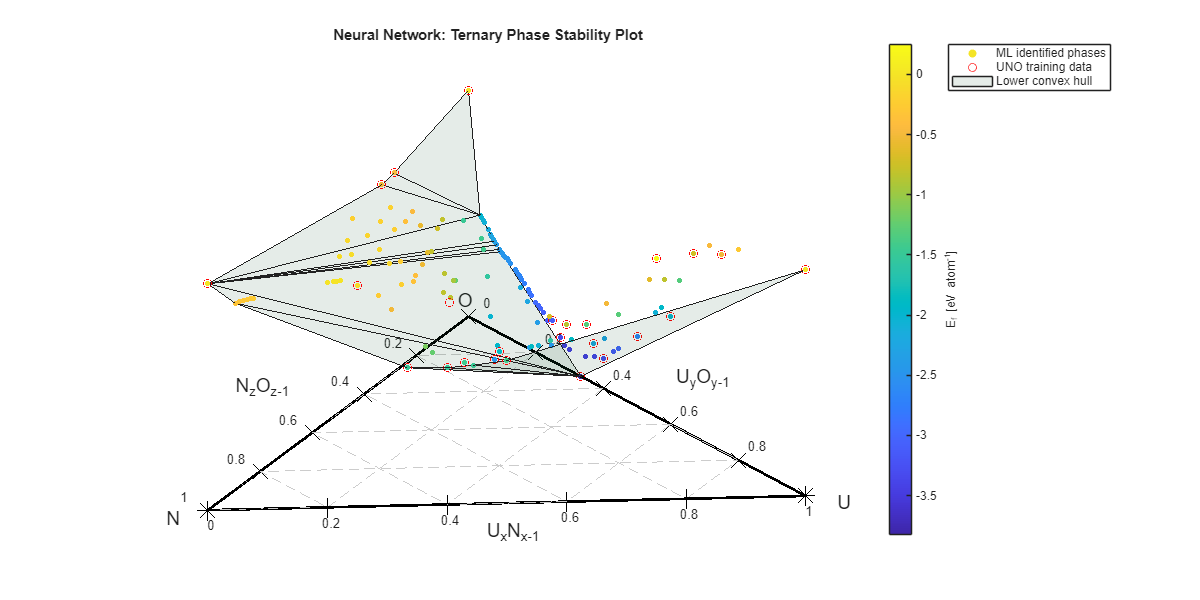

Stable Phases identified via Neural Network learning:
              Ef_eV  
             ________

    U2N3      -1.5127
    U2O19     -2.4365
    U4N5      -1.4788
    UN        -1.4158
    UN2       -1.4952
    UN21     -0.33764
    UO10      -2.4106
    UO11      -2.3587
    UO12      -2.3136
    UO2       -3.8193
    UO28      -2.0021
    NO2        -0.507
    N2O5       -0.463
    N               0
    U               0
    O               0

Metastable Phases identified via Neural Network learning:
              Ef_eV  
             ________

    U2O11     -2.6888
    U2O15      -2.516
    U2O17 

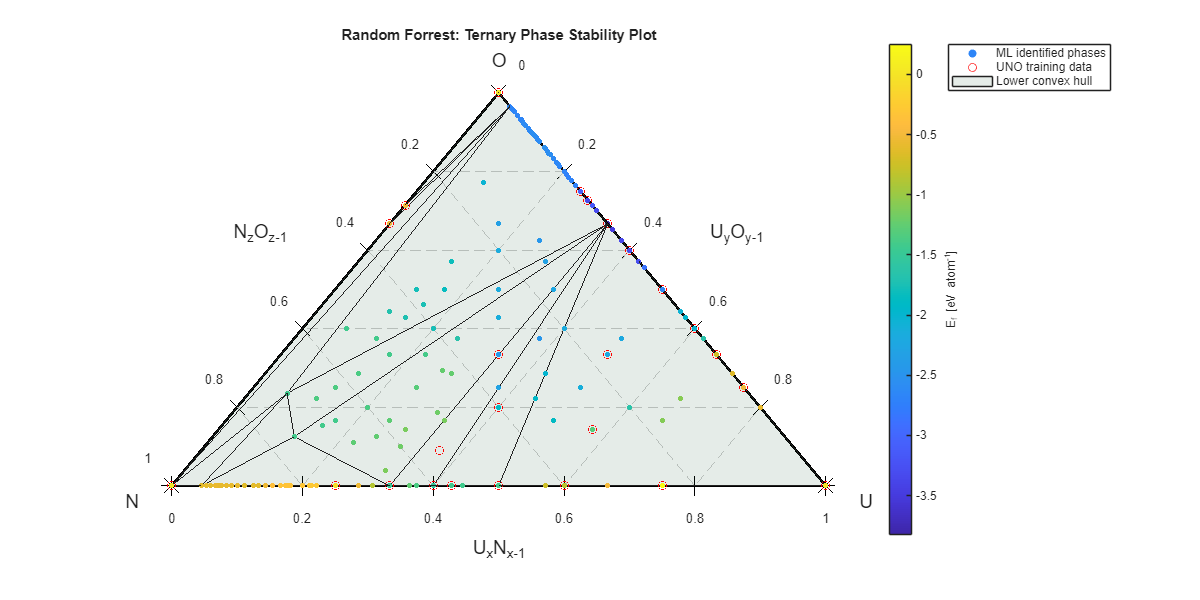

Stable Phases identified via Random Forrest learning:
                Ef_eV  
               ________

    U(N3O)4     -1.4272
    U2N3        -1.5127
    UN          -1.4158
    UN2         -1.4952
    UN21       -0.59572
    UN6O         -1.408
    UO2         -3.8193
    UO28        -2.6835
    NO2          -0.507
    N2O5         -0.463
    N                 0
    U                 0
    O                 0

Metastable Phases identified via Random Forrest learning:
               Ef_eV  
              ________

    U2NO       -2.1239
    U2O49      -2.6835
    U3N2O      -1.8735
    U3N3O2     -2.2964
    U3N4     

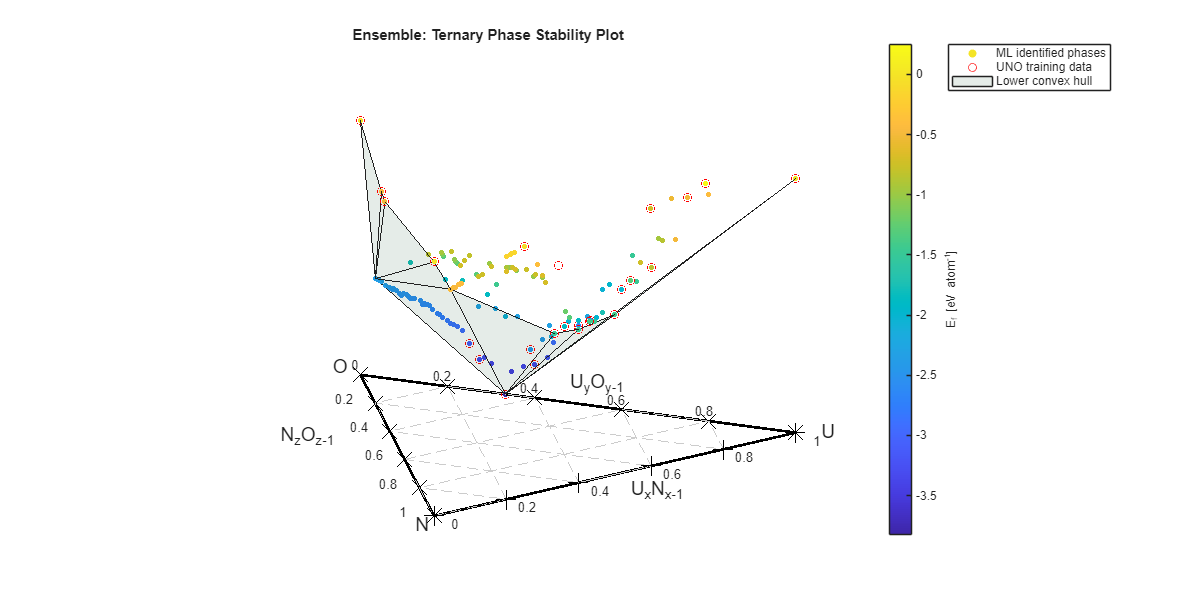

Stable Phases identified via Ensemble learning:
             Ef_eV  
            ________

    U2N3     -1.5127
    UN       -1.4158
    UN2      -1.4952
    UN21    -0.46668
    UO2      -3.8193
    UO28     -2.3428
    NO2       -0.507
    N2O5      -0.463
    N              0
    U              0
    O              0

Metastable Phases identified via Ensemble learning:
              Ef_eV  
             ________

    U2O25     -2.4711
    U2O27     -2.4603
    U2O3      -3.3237
    U2O49     -2.3594
    U3N4      -1.4348
    U3O4      -3.1908
    U3O8       -3.349
    U4N5      -1.4533
    U

% - - - - - - - - - - - - - - - - - - - - - Ternary Plotting and Output - - - - - - - - - - - - - - - - - - - - -  

tic
for i = 2:4
    ternary_stable_phase_plotting(clean{i},results{i},results{1},clean{1}, 1, 1) % add a label stable and label metastable phase option
end

toc

Elapsed time is 0.716799 seconds.


% - - - - - - - - - - - - - - - - - - - - - Relevent functions to script - - - - - - - - - - - - - - - - - - - - - 

function ternary_stable_phase_plotting(T,R,tR,tT,view3d,uv_axis)

    % T = table containing all data from the datapreprocessing
    % R = structure containing all teh data from the stable phase identification
    % if preceded by "t" its the same but for the UNO training data
    % view3d = 0 or 1 if 0 we look at ot from top down by default
    % uv_axis = 0 or 1 : if 0 we dont display the u-v external axis (transform vectors)
    
    train_u = tR.u;
    train_v = tR.v;
    train_x4 = tT{:,"Ef_eV"};
    u = R.u;
    v = R.v;
    
    
    p = [-1/sqrt(2), 1/sqrt(2), 0];
    q = [-1/sqrt(6), -1/sqrt(6), 2/sqrt(6)];
    
    %x1 = T{:,"N"};
    %x2 = T{:,"U"};
    %x3 = T{:,"O"};
    x4 = T{:,"Ef_eV"};
    k = R.k;

    f = figure;
    f.Position = [100, 100, 1200, 600];
    
    % ML identified points
    scatter3(u, v, x4, 15, x4, "filled")
    %T = [T, table(u,VariableNames={'u'}), table(v,VariableNames={'v'})]   ! ! ! !DOESNT WORK ! ! !
    %scatter3(T, 'u', 'v', 'Ef_eV', 15, 'Ef_ev', "filled") %plotting from a tabe lets us see rownames (formulae) when hovering cursour over a point
    hold on
    
    % training data
    scatter3(train_u,train_v,train_x4, 'or')

    % convex hull
    ts = trisurf(k, u, v, x4);
    ts.FaceAlpha = 0.1;
    ts.FaceColor = '#04471C';

    floor_of_plot = min(x4);
    
    % - - - - - axis, labels, chevrons, and grid generation - - - - - 
    marker_spacing = 0.1;
    ternary_axis_generation(p,q,floor_of_plot,marker_spacing,0.1)
    
    % colourbar
    cd = colorbar();
    cd.Label.String = 'E_f [eV atom^-^1]';

    xlabel('u [arb. units]')
    ylabel('v [arb units]')
    zlabel('E_f [eV]')
    title([R.learningtype,': Ternary Phase Stability Plot'])
    %ylim([q(1)-3*marker_spacing q(3)+3*marker_spacing])   % setting limits with axis() 
    %axis equal 
    
    axis([ min(p)-3*marker_spacing max(p)+3*marker_spacing min(q)-3*marker_spacing max(q)+3*marker_spacing floor_of_plot max(x4) ])
    
    % checking user-given display settings
    if logical(uv_axis)
        axis off
        axis([min(p)-1*marker_spacing    max(p)+1*marker_spacing ...
              min(q)-1.5*marker_spacing  max(q)+1.5*marker_spacing ...
              floor_of_plot              max(x4) ])
    else
        axis([min(p)-3*marker_spacing max(p)+3*marker_spacing ...
              min(q)-3*marker_spacing max(q)+3*marker_spacing ...
              floor_of_plot           max(x4) ])
    end
    grid off
    if ~logical(view3d)
        view([360.00 90.00])
    end
    legend({'ML identified phases','UNO training data','Lower convex hull'})
    hold off
    
    disp(['Stable Phases identified via ',R.learningtype,' learning:'])
    disp(T(R.spid,"Ef_eV"))
    disp(['Metastable Phases identified via ',R.learningtype,' learning:'])
    disp(T(R.mspid,"Ef_eV"))
    
end

function ternary_axis_generation(p,q,floor_of_plot,marker_spacing,vertex_spacing)

    % our pure phases will be always atthe points we use to define our variable change
    vertexs = [p(end-2), q(end-2);    % N
               p(end-1), q(end-1);    % U
               p(end)  , q(end)  ;    % O
               p(end-2), q(end-2)];   % N again to aid cyclic permutation notation
    
    plot3([vertexs(1:2,1)],[vertexs(1:2,2)],[floor_of_plot,floor_of_plot],'k', LineWidth=2)
    plot3([vertexs(2:3,1)],[vertexs(2:3,2)],[floor_of_plot,floor_of_plot],'k', LineWidth=2)
    plot3([vertexs(3:4,1)],[vertexs(3:4,2)],[floor_of_plot,floor_of_plot],'k', LineWidth=2)
    
    pmarkers = [linspace(vertexs(1,1),vertexs(2,1),6);  % NU
                linspace(vertexs(2,1),vertexs(3,1),6);  % UO
                linspace(vertexs(3,1),vertexs(4,1),6)]; % UO
    qmarkers = [linspace(vertexs(2,2),vertexs(2,2),6);  % NU
                linspace(vertexs(2,2),vertexs(3,2),6);  % UO
                linspace(vertexs(3,2),vertexs(4,2),6)]; % UO;
    markertext = {'0','0.2','0.4','0.6','0.8','1';
                  ' ','0.8','0.6','0.4','0.2','0';
                  ' ','0.2','0.4','0.6','0.8','1'};
    plot3(pmarkers(1,:), qmarkers(1,:), ones(6,1)*floor_of_plot, '+k', 'MarkerSize',15)
    plot3(pmarkers(2:3,:), qmarkers(2:3,:), ones(6,1)*floor_of_plot, 'xk', 'MarkerSize',15) % if I want different NU markers uncomment and change index in next line from 1:2 to 2:2
    
    % axis marker labeling
    %marker_spacing = 0.1;
    pmarker_labels(:,:) = [pmarkers(1,:)                         ; %
                           pmarkers(2,:)+marker_spacing*sin(pi/6);
                           pmarkers(3,:)-marker_spacing*sin(pi/6)];
    qmarker_labels(:,:) = [qmarkers(1,:)-marker_spacing          ; %
                           qmarkers(2,:)+marker_spacing*cos(pi/6);
                           qmarkers(3,:)+marker_spacing*cos(pi/6)];
    text(pmarker_labels(:), qmarker_labels(:), ones(18,1)*floor_of_plot, markertext,'FontSize',10,'HorizontalAlignment','center')
    
    % axis labeling
    axis_labels = [mean(vertexs(1:2,1)), mean(vertexs(1:2,2)) - 2*marker_spacing;
                   mean(vertexs(2:3,1))+2*marker_spacing*sin(pi/6), mean(vertexs(2:3,2))+2*marker_spacing*cos(pi/6); 
                   mean(vertexs(3:4,1))-2*marker_spacing*sin(pi/6), mean(vertexs(3:4,2))+2*marker_spacing*cos(pi/6)];
    text(axis_labels(1,1),axis_labels(1,2),floor_of_plot,'U_xN_x_-_1', 'FontSize',14, 'HorizontalAlignment','center')
    text(axis_labels(2,1),axis_labels(2,2),floor_of_plot,'U_yO_y_-_1', 'FontSize',14, 'HorizontalAlignment','left')
    text(axis_labels(3,1),axis_labels(3,2),floor_of_plot,'N_zO_z_-_1', 'FontSize',14, 'HorizontalAlignment','right')
    
    % vertex labels
    %vertex_spacing = 0.05; % adding some room between vertexes and their labels
    vertex_labels = [vertexs(1,1)-vertex_spacing*cos(pi/6),vertexs(1,2)-vertex_spacing*sin(pi/6), floor_of_plot;
                     vertexs(2,1)+vertex_spacing*cos(pi/6),vertexs(2,2)-vertex_spacing*sin(pi/6), floor_of_plot;
                     vertexs(3,1)                         ,vertexs(3,2)+vertex_spacing          , floor_of_plot];
    text(vertex_labels(1,1),vertex_labels(1,2),vertex_labels(1,3), 'N','FontSize',14,'HorizontalAlignment','center')
    text(vertex_labels(2,1),vertex_labels(2,2),vertex_labels(2,3), 'U','FontSize',14,'HorizontalAlignment','center')
    text(vertex_labels(3,1),vertex_labels(3,2),vertex_labels(3,3), 'O','FontSize',14,'HorizontalAlignment','center')
    
    % gridlines
    % go from n in 1 marker array to end -n in the subsequent marker array
    
    gridpoints = [pmarkers(1,1+1), qmarkers(1,1+1);     % positive diagonals
                  pmarkers(2,6-1), qmarkers(2,6-1);
                  pmarkers(2,6-2), qmarkers(2,6-2);
                  pmarkers(1,1+2), qmarkers(1,1+2);
                  pmarkers(1,1+3), qmarkers(1,1+3);
                  pmarkers(2,6-3), qmarkers(2,6-3);
                  pmarkers(2,6-4), qmarkers(2,6-4);
                  pmarkers(1,1+4), qmarkers(1,1+4);     % negative diagonals
                  pmarkers(3,1+1), qmarkers(3,1+1);
                  pmarkers(3,1+2), qmarkers(3,1+2);
                  pmarkers(1,6-2), qmarkers(1,6-2);
                  pmarkers(1,6-3), qmarkers(1,6-3);
                  pmarkers(3,1+3), qmarkers(3,1+3);
                  pmarkers(3,1+4), qmarkers(3,1+4);
                  pmarkers(1,6-4), qmarkers(1,6-4);     % horizontal, need to round the corner first
                  pmarkers(1,1+0), qmarkers(1,1+0);     % going via the UNO corner of the plot
                  pmarkers(3,6-1), qmarkers(3,6-1);
                  pmarkers(2,1+1), qmarkers(2,1+1);
                  pmarkers(2,1+2), qmarkers(2,1+2);
                  pmarkers(3,6-2), qmarkers(3,6-2);
                  pmarkers(3,6-3), qmarkers(3,6-3);
                  pmarkers(2,1+3), qmarkers(2,1+3);
                  pmarkers(2,1+4), qmarkers(2,1+4);
                  pmarkers(3,6-4), qmarkers(3,6-4)];
    
    plot3(gridpoints(:,1), gridpoints(:,2), ones(length(gridpoints(:,1)),1)*floor_of_plot, '--','Color',[0.8 0.8 0.8 0.2])
end
    

function [spid, mspid, u, v, k] = define_stable_phases(T,deltaE_metastable,show_change_of_basis)
    % function that returns the id's of stable phases (spid) and the id's of
    % metastable phases (mspid), dependant of definition of metastable, where
    % deltaE_metastable is the height above the convex hull to define as
    % metastable.
    
    x1 = T{:,"N"};
    x2 = T{:,"U"};
    x3 = T{:,"O"};
    x4 = T{:,"Ef_eV"};
    
    % p and q are the vectors that span the plane (x+y+z=1) that all the points
    % in x1,x2,x3 (3d) space lie on. If we change variables to p & q then we
    % can express this as a 3d convex hull problem rather than 4d.
    
    %        O       the point (.) is the UNO point where all fractions are a third
    %       / \      p runs paralell to N->U, from (.) , and q runs from (.)->O
    %      /   \
    %     /  .  \ 
    %    /       \
    %   /_________\
    %  N           U
    
    % if you want to see a proper plot, change the "show change of basis"
    % variable to 1
    
    if show_change_of_basis == 1
        scatter3(x1,x2,x3,10,x4,"filled")
        hold on 
        [X,Y] = meshgrid(0:0.1:1, 0:0.1:1);
        Z = 1 - X - Y;
        s = surf(X,Y,Z);
        s.FaceAlpha = 0.1;
        %plot3([1/3,1],[1/3,1],[1/3,1],'-r')
        plot3([0,1/sqrt(3)],[0,1/sqrt(3)],[0,1/sqrt(3)],'r')
        plot3([1,0],[0,1],[0,0],'g')
        plot3([0,1/2],[0,1/2],[1,0],'b')
        %plot3([0,1/sqrt(3)],[0,1/sqrt(3)],[0,1/sqrt(3)],'--g',LineWidth=2)
        view([495.000 35.000])
        xlabel('N')
        ylabel('U')
        zlabel('O')
        xlim([0 1])
        ylim([0 1])
        zlim([0 1])
        legend({'points spanning the plane','plane','p','q','r'})
        hold off
        clear X Y Z s
    end
    
    p = [-1/sqrt(2), 1/sqrt(2), 0];
    q = [-1/sqrt(6), -1/sqrt(6), 2/sqrt(6)];
    u = zeros(length(x1),1);
    v = zeros(length(x1),1);
    x_frac = [x1,x2,x3];
    for i = 1:length(x1)
    u(i) = dot(p,x_frac(i,:));
    v(i) = dot(q,x_frac(i,:));
    end
    
    % defining convex hull of stable phases (some false ids to be removed still)
    k = convhull(u,v,x4);
    
    % if a point is less than 0.1 eV above the lower hull, it is metastable
    % some literature says 80 meV but staying at 0.1 for now
    
    % I will move each point, in turn, down by the metastable phase def and if
    % there is a change to the convex hull, then its metastable 
    
    k_numb_nodes = height(k);
    mspid = zeros(height(T),1);
    kids = T{unique(k(:)),'id'};
    for i = 1:height(T)
        pertubated_x4 = x4;
        pertubated_x4(i) = pertubated_x4(i) - deltaE_metastable;
        kms = convhull(u,v,pertubated_x4);
        kmsids = T{unique(kms(:)),'id'};
        if height(kms) ~= k_numb_nodes
            mspid(i) = T{i,'id'};
        elseif kmsids ~= kids
            mspid(i) = T{i,'id'};
        end
    end
    mspid = nonzeros(mspid);
    disp([num2str(k_numb_nodes),' convex hull nodes identified'])
    disp([num2str(length(mspid)),' metastable phases found on first pass'])
    
    % need to systematically remove planes from k
    planes_to_remove = zeros(height(k),1);
    kx4 = x4(k);
    
    % identifying all stable phases on the edges of the triangle
    T_nitrogen = T;
    T_nitrogen(contains(T.Properties.RowNames, 'O'), :) = [];
    T_nitrogen = sortrows(T_nitrogen,"N","ascend");
    [~, bspN] = binary_stable_phase_identification(T_nitrogen{:,"N"},T_nitrogen{:,"Ef_eV"});
    trmN = zeros(height(T_nitrogen),1);
    trmN(bspN) = 1;
    T_rmN = T_nitrogen;
    T_rmN(logical(trmN),:) = []; % now T_nitrogen has all the stable phses removed, now a list of items to remove from our k matrix
    T_oxygen = T;
    T_oxygen(contains(T.Properties.RowNames, 'N'), :) = [];
    T_oxygen = sortrows(T_oxygen,"O","ascend");
    [~, bspO] = binary_stable_phase_identification(T_oxygen{:,"O"},T_oxygen{:,"Ef_eV"});
    trmO = zeros(height(T_oxygen),1);
    trmO(bspO) = 1;
    T_rmO = T_oxygen;
    T_rmO(logical(trmO),:) = []; % now T_oxygen has all the stable phses removed, now a list of items to remove from our k matrix
    
    bnsp = vertcat(T_rmN{:,'id'},T_rmO{:,'id'}); %id's of all binary phases that arent stable
    % this however, still leaves plaes between stable phases, that are not the lower convex hull
    bspUN = T_nitrogen{bspN,"id"};
    bspUO = T_oxygen{bspO,"id"};
    
    T_no_metal = T;
    T_no_metal(contains(T.Properties.RowNames, 'U'), :) = [];
    bspNO = [T_no_metal{:,'id'}];
    
    
    for i = 1:height(k)
        % remove top layer(s)
        if max(kx4(i,:)) > 0
            planes_to_remove(i) = 1;
        elseif sum(kx4(i,:)) == 0
            planes_to_remove(i) = 1;
        end
        % remove all binary non-stable phases
        if min(abs(k(i,1)-bnsp)) == 0 || min(abs(k(i,2)-bnsp)) == 0 || min(abs(k(i,3)-bnsp)) == 0
            planes_to_remove(i) = 1;
        % if a plane only connects to binary stable pases of the samy type then
        % its not in the lower convex hull.
        elseif min(abs(k(i,1)-bspUN)) == 0 && min(abs(k(i,2)-bspUN)) == 0 && min(abs(k(i,3)-bspUN)) == 0
            planes_to_remove(i) = 1;
        elseif min(abs(k(i,1)-bspUO)) == 0 && min(abs(k(i,2)-bspUO)) == 0 && min(abs(k(i,3)-bspUO)) == 0
            planes_to_remove(i) = 1;
        elseif min(abs(k(i,1)-bspNO)) == 0 && min(abs(k(i,2)-bspNO)) == 0 && min(abs(k(i,3)-bspNO)) == 0
        planes_to_remove(i) = 1;
        end
    end
    disp([num2str(sum(planes_to_remove)),' planes removed'])
    
    k(logical(planes_to_remove),:) = [];
    spid = T{unique(k(:)),'id'};
    
    
    rm_msp_id = zeros(size(mspid));
    for i = 1:length(mspid)
        if min(abs(mspid(i) - spid)) == 0
            rm_msp_id(i) = 1;
        end
    end
    mspid(logical(rm_msp_id)) = [];
    
    disp([num2str(length(spid)),' stable-phases and ',num2str(length(mspid)),' metastable-phases identified after trimming to lower covex hull'])

end

function [y_pl, stable_phases] = binary_stable_phase_identification(frac,ef)
    % function that generates the piecewise linear line between stable
    % phases and identifies what phases are stable (to plot afterwards)

    %x = T{:,"oxidant_fraction"};
    %y = T{:,"Ef_eV"};

    % Stable Phase Identification 
    
    residual = ef;
    nodes = [1,length(frac)]; % starting with nodes at the stable pure phases (labeled as array indexes)
    
    halt = 0;
    while halt == 0
        % loop over our new node generation untill there are no new nodes required
        % to bound our formation energies from below with piecewise liniarity     
        [residual, nodes, halt] = binary_node_identification(frac,residual,nodes);
    end
    %stable_phases = ismember(residual,0); 
    % used to calculate off of i the residual was 0 but floating point 
    % error got in the way, just using node positions, far simpler
    stable_phases = nodes;
    
    %[stable_phases,y_pl,y]
    
    % the piecewise linear plot is the diference between our residual and our unaltered data
    y_pl = ef - residual;
end

function [residual, nodes, halt_condition] = binary_node_identification(x,y,nodes)
    % this function is used iterativly. When given the dataset of Ef wrt to
    % phase, it will identify the global minimum and partition it into 2 PL
    % segments. Further iterations will find points below the residual and 
    % generate a new node. This is repeted untill there are no phases below
    % our PL curve.
    % original residual is wrt PL between pure phases.

    % if points below our current line we need an aditional node to
    % describe this stable phase 
    
     
    [~, node] = min(y);
    %disp(x(node))
    if ismember(node, nodes)
        halt_condition = 1;
        residual = y;
        return;
    end
    nodes = [nodes,node];
    nodes = sort(nodes);

    [~, node_idx] = min(abs(nodes - node));
    nodeLHS = nodes(node_idx-1); % left neighbour
    nodeRHS = nodes(node_idx+1); % right neighbour

    % find line connecting neighboring nodes to this new one
    % generating peicwise linearity with y = m x - m*xNode + yNode. Where: m = (yNeibour - yNode) / (xNeibour - xNode) 
    % xI and yI are node coordinates in Ef eV/atom and nitrogen fraction.
    y_plLHS = ((y(nodeLHS) - y(node)) / (x(nodeLHS) - x(node))).*x ...   % peicewise linearity new node and LHS node neighbour
             -((y(nodeLHS) - y(node)) / (x(nodeLHS) - x(node)))*x(node) + y(node);
    y_plRHS = ((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node))).*x ...   % peicewise linearity new node and RHS node neighbour
             -((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node)))*x(node) + y(node);
    y_pl = vertcat(y_plLHS(1:node),y_plRHS(node+1:end));
    %( (y(nodeLHS) - y(node) ) / ( x(nodeLHS) - x(node) ) )
    %((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node)))

    residual = y;
    residual(nodeLHS:nodeRHS) = residual(nodeLHS:nodeRHS) - y_pl((nodeLHS:nodeRHS));
    %disp(['Stable Nodes [oxidant-fraction]:    ',num2str(x(nodes).')])
    
    % checking if another iteration will be required.
    newnode_val = min(residual);
    if newnode_val >= 0
        halt_condition = 1;
        %disp(['No new nodes to find, ', num2str(length(nodes)),' stable phases found'])
        nodes = unique(nodes); % otehrwise numerical error can cause double counting 
    else
        halt_condition = 0;
    end
    
end

function frac = define_compsition_axis(formula)
    % - - - - - define_composition_axis - - - - - - - HARDCODED FOR TERNARY UxNyOz
    % we now have formulae of the form - UxIyJz or Ux(IyJz)n where I & J are
    % our oxidants (U and N), we can now have groups in our solid (in brackets)
    % with their own stoichiometry, to develop fractions we will need to regen
    % a machine readable version of the formula with UxI(y*n)J(z*n) parallel to
    % the formulae array to read teh fracional composition fractions.
    
    formula = char(formula);
    
    stoich = zeros(3,1);
    stoich(1) = get_stoichiometry(formula,'N');   % number of N in formula
    stoich(2) = get_stoichiometry(formula,'U');   % number of U in formula
    stoich(3) = get_stoichiometry(formula,'O');   % number of O in formula
    
    frac = zeros(3,1);
    for i = 1:3
        frac(i) = stoich(i) / (sum(stoich(:)));
    end
end

function stoich = get_stoichiometry(formula,element)
    % searches for all consecutive digits after a given starting point and
    % returns the number ie reads U1234NO as 1234. if told to look for 'U'
    % in the character array.
    element_idx = strfind(formula,element);
    formula = [formula(element_idx+1:end),'|'];     % only considering the relevent part of the formula and adding a stopper to the end "|" so we never have an empty string
    i = 1;
    stoich = 0;
    %disp(['is ',formula(i),' a digit?: ',num2str(~isnan(str2double(formula(i))))])
    if isnan(str2double(formula(i))) && ~isempty(element_idx) % logical if the i-th char in the string is NOT a digit 
        %disp('No subsequent digits')
        stoich = 1;            % if no number follows our element then stoich is 1 (AB2 = A1B2)
    elseif ~isnan(str2double(formula(i)))
        %disp('∃ subsequent digits')
        while ~isnan(str2double(formula(i)))
            stoich = stoich + 10^(1-i)*str2double(formula(i)); % appending new digit 1 dp lower than last
            i = i+1;    % incrementing counter
        end
        stoich = stoich*10^(i-2); % multiplying up by 10 ^ (number of digits appended)
        %disp(stoich)
    end
    % as we can have formulae of the form Ux(IyJz)n we need to check for
    % brackets and retun stoich of y*n and z*n
    
    open_bracket = strfind(formula,'(');
    close_bracket = strfind(formula,')');
    if isempty(open_bracket) && ~isempty(close_bracket) % as we remove  char before our element if open bracket is missing then we are in the brackets
        stoich = stoich * str2double(formula(close_bracket+1:end-1)); % only works with assumption that the last item is our brackets and we have only 1 set of brackets
    end

end






